Brief summary of this function.

Detailed explanation of this function.

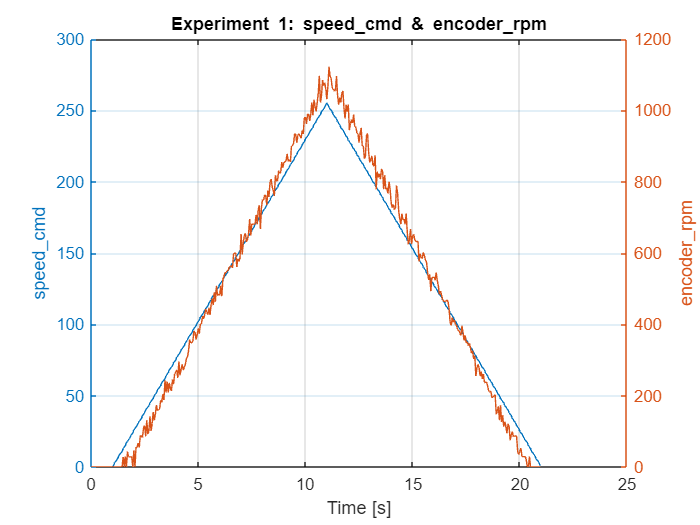

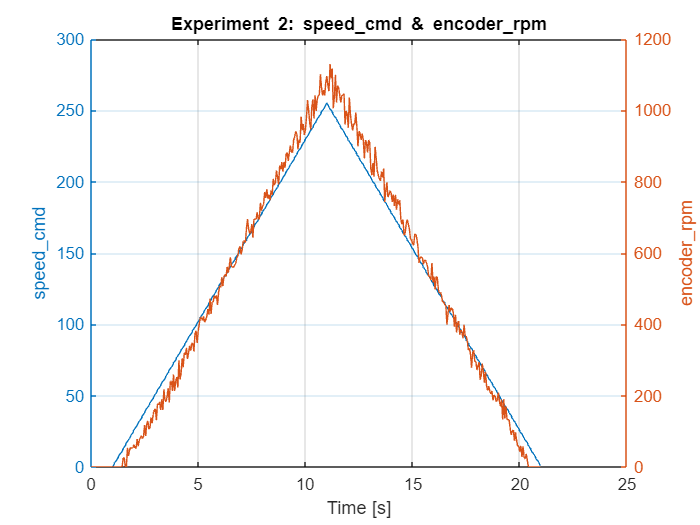

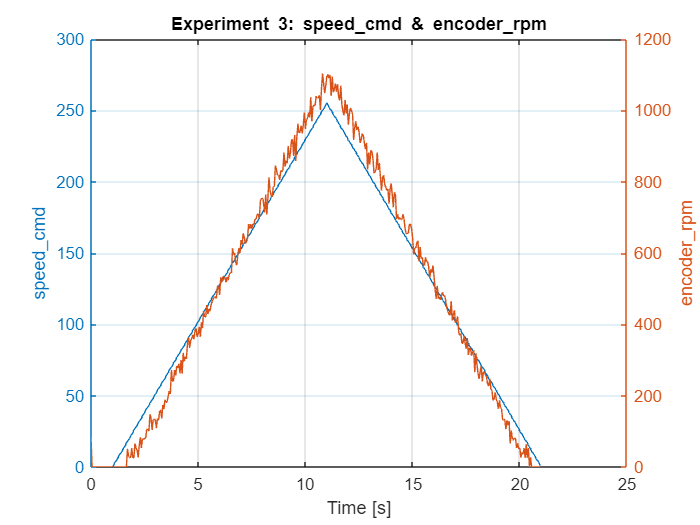

%% 1. Nạp dữ liệu từ các file .mat

% Gom vào cell để xử lý chung
expAll = { ...
    rampResult1, ...
    rampResult2, ...
    rampResult3 };

nExp = numel(expAll);

% Tham số người dùng
nIdleSamples = 30;   % số mẫu đầu để ước lượng nhiễu
kNoiseStd    = 3;    % hệ số nhân std để đặt ngưỡng
showFigures  = true;


%% 2. Kiểm tra ramp theo thời gian (speed\_cmd và encoder\_rpm)

if showFigures
    for k = 1:nExp
        data = expAll{k};

        t = data.t(:);
        u = data.speed_cmd(:);
        y = data.encoder_rpm(:);

        figure('Name',sprintf('Exp %d - ramp time plot',k));
        yyaxis left
        plot(t,u,'-'); grid on
        ylabel('speed\_cmd')
        yyaxis right
        plot(t,y,'-');
        ylabel('encoder\_rpm')
        xlabel('Time [s]')
        title(sprintf('Experiment %d: speed\\_cmd & encoder\\_rpm',k));
    end
end

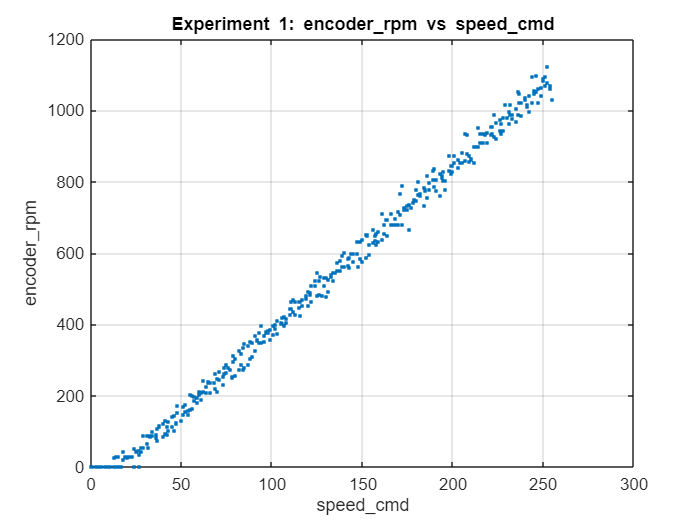

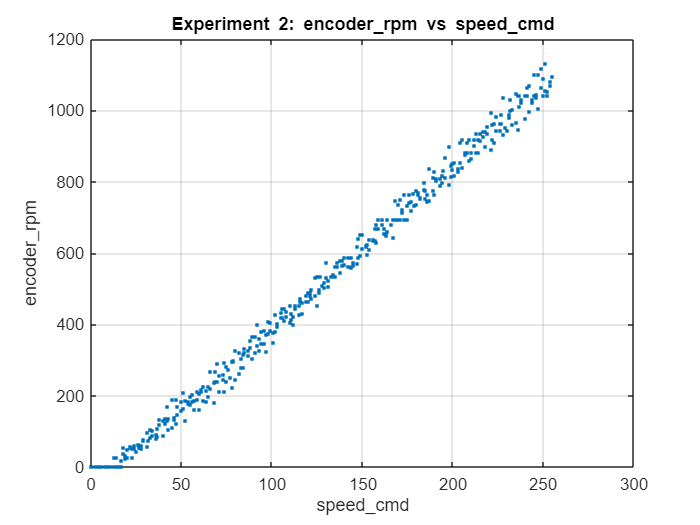

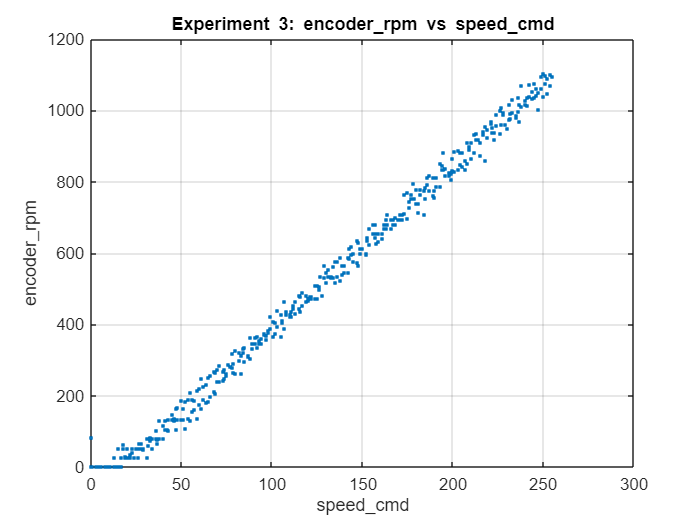



%% 3. Đặc tính tĩnh encoder\_rpm theo speed\_cmd

if showFigures
    for k = 1:nExp
        data = expAll{k};

        u = data.speed_cmd(:);
        y = data.encoder_rpm(:);

        figure('Name',sprintf('Exp %d - static characteristic',k));
        plot(u,y,'.'); grid on
        xlabel('speed\_cmd')
        ylabel('encoder\_rpm')
        title(sprintf('Experiment %d: encoder\\_rpm vs speed\\_cmd',k));
    end
end



%% 4. Ước lượng nhiễu ở trạng thái đứng yên

noiseStats = struct('yIdleMax',[],'yIdleStd',[],'rpmThresh',[]);

for k = 1:nExp
    data = expAll{k};
    y = data.encoder_rpm(:);

    y_idle = y(1:min(nIdleSamples,numel(y)));

    noiseStats(k).yIdleMax = max(abs(y_idle));
    noiseStats(k).yIdleStd = std(y_idle,1);
    noiseStats(k).rpmThresh = noiseStats(k).yIdleMax + kNoiseStd*noiseStats(k).yIdleStd;
end


%% 5. Tìm deadband cho từng thí nghiệm (chiều dương / âm)

deadbandPerExp = struct( ...
    'u_db_pos',NaN,'t_db_pos',NaN, ...
    'u_db_neg',NaN,'t_db_neg',NaN);

for k = 1:nExp
    data = expAll{k};

    t  = data.t(:);
    u  = data.speed_cmd(:);
    y  = data.encoder_rpm(:);
    thr = noiseStats(k).rpmThresh;

    % Deadband phía dương
    idxPos = find( (y >  thr) & (u > 0), 1, 'first');
    if ~isempty(idxPos)
        deadbandPerExp(k).u_db_pos = u(idxPos);
        deadbandPerExp(k).t_db_pos = t(idxPos);
    end

    % Deadband phía âm (nếu có)
    idxNeg = find( (y < -thr) & (u < 0), 1, 'first');
    if ~isempty(idxNeg)
        deadbandPerExp(k).u_db_neg = u(idxNeg);
        deadbandPerExp(k).t_db_neg = t(idxNeg);
    end
end


%% 6. Tổng hợp deadband giữa 3 thí nghiệm

u_db_pos_all = [deadbandPerExp.u_db_pos];
u_db_neg_all = [deadbandPerExp.u_db_neg];

u_db_pos_mean = mean(u_db_pos_all(~isnan(u_db_pos_all)));
u_db_neg_mean = mean(u_db_neg_all(~isnan(u_db_neg_all)));

u_db_sym = max(abs([u_db_pos_mean, u_db_neg_mean]));  % deadband đối xứng (tùy chọn)

deadbandSummary = struct( ...
    'u_db_pos_each', u_db_pos_all, ...
    'u_db_neg_each', u_db_neg_all, ...
    'u_db_pos_mean', u_db_pos_mean, ...
    'u_db_neg_mean', u_db_neg_mean, ...
    'u_db_sym',      u_db_sym);

deadbandSummary

deadbandSummary = struct with fields:
    u_db_pos_each: [13 13 45]
    u_db_neg_each: NaN
    u_db_pos_mean: 23.6667
    u_db_neg_mean: NaN
         u_db_sym: 23.6667




%% 7. Ghi kết quả deadband vào lại từng struct rồi lưu

for k = 1:nExp
    data = expAll{k};

    data.deadband.u_db_pos  = deadbandPerExp(k).u_db_pos;
    data.deadband.u_db_neg  = deadbandPerExp(k).u_db_neg;
    data.deadband.rpmThresh = noiseStats(k).rpmThresh;
    data.deadband.u_db_sym  = u_db_sym;

    switch k
        case 1
            baselineCharacteristicsExperiment1 = data;
            save('baselineCharacteristicsExperiment1_withDeadband.mat', ...
                 'baselineCharacteristicsExperiment1');
        case 2
            baselineCharacteristicsExperiment2 = data;
            save('baselineCharacteristicsExperiment2_withDeadband.mat', ...
                 'baselineCharacteristicsExperiment2');
        case 3
            baselineCharacteristicsExperiment3 = data;
            save('baselineCharacteristicsExperiment3_withDeadband.mat', ...
                 'baselineCharacteristicsExperiment3');
    end
end
